# Finite temperatures: Purification and XTRG

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we implement two different approaches for simulating thermal states based on imaginary-time evolution.

- The **purification** method represents a thermal density matrix as a "super-vector" that acts on the physical and auxiliary spaces. The purified thermal state undergoes imaginary-time evolution by applying Trotter-decomposed time evolution operators. In this scheme, the imaginary-time instance, corresponding to the inverse temperature, increases linearly.

- The **exponential tensor renormalization group (XTRG)**, first developed in Chen2018 [[B.-B. Chen, L. Chen, Z. Chen, W. Li, and A. Weichselbaum, Phy. Rev. X **8**, 031082 (2018)](https://journals.aps.org/prx/abstract/10.1103/PhysRevX.8.031082)], represents a thermal density matrix as an MPO $\tilde{\rho} (\tau) = \exp (-\tau \hat{H})$. By multiplying two MPOs, one gets another MPO representation of the thermal state for a half of the temperature: $\tilde{\rho}(2\tau) = \tilde{\rho}^\dagger (\tau) \tilde{\rho}(\tau)$. In other words, the imaginary-time instance increases logarithmically; see Fig. 2(a) of Chen2018.

In Exercises (b) and (c), we will complete the purification method and the XTRG, respectively, and apply them to compute the partition function of the XY spin-1/2 chain,


$$\hat{H}_{\mathrm{XY}}
= -\sum_{\ell=1}^{L-1} (\hat{S}_{\ell,x} \hat{S}_{\ell+1,x} + \hat{S}_{\ell,y} \hat{S}_{\ell+1,y})
= -\frac{1}{2} \sum_{\ell=1}^{L-1} (\hat{S}_{\ell,+} \hat{S}_{\ell+1,-} + \hat{S}_{\ell,-} \hat{S}_{\ell+1,+}) .$$


As we discussed many times in previous tutorials, this model is analytically solvable. Especially, the partition function of the system at temperature $T$ is given by


$$Z = \prod_{k = 1}^{L} (1 + e^{-\beta \epsilon_k}),$$


where $\beta = 1/T$ is the inverse temperature and $\epsilon_k = - \cos( k\pi / (L+1))$ is the single-particle eigen-energies.

For a fair comparison, we choose parameters so that the both approaches reach the inverse temperature $\beta = 100$ in 40 iterations.

## Exercise (a): Complete the function for variational multiplication of MPOs

The common part of the two different approaches is MPO multiplication.

- At each iteration in the purification method, the MPO representation of a time evolution operator $\exp (-\Delta \tau \hat{H})$ multiplies to the MPO representation of the purified thermal state at imaginary time $-\mathrm{i} \tau$, leading to the purified state at $-\mathrm{i} (\tau + \Delta \tau)$.

- At each iteration in the XTRG, the MPO representations of $\tilde{\rho}^\dagger (\tau)$ and $\tilde{\rho} (\tau)$ are multiplied, leading to $\tilde{\rho} (2\tau)$.

For the MPO multiplication, we use the function `mtimes_MPO_Ex.m`, included in the same sub-directory with this script. The function is supposed to perform variational multiplication of MPOs, where the multiplication result MPO is optimized via two-site update, which is similar to the ground and excited states search within the DMRG. See App. D 1 of Chen2018 for the details of the variational MPO multiplication.

The function `mtimes_MPO_Ex.m` is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

## Exercise (b): Complete the function for the purification method

Once you complete `mtimes_MPO_Ex.m`, you can use it as a key sub-routine for the purification method, which is partially implemented in `finT_puri.m`, which is also included in the same sub-directory. Complete the parts of `finT_puri.m` enclosed by the comments `TODO (start)` and `TODO (end)`.

To verify the codes, we compute the partition function of the XY spin chain. The numerical result and the exact values can be compared by running the script below.

clear

% system parameter
J = -1; % coupling strength
L = 20; % number of sites in a chain

% imaginary-time evolution parameters
beta = 100; % inverse temperature
tmax = beta/2;

Note that $\tau_\max = \beta / 2$, since in the purification method only a half of the imaginary-time evolution is performed.

Nstep = 40; % # of iterations
dt = tmax/Nstep; % time step
Nkeep = 30; % maximum bond dimension
Nsweep = 4; % # of round-trip sweeps in the variational multiplication

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

The `finT_puri` function has the input syntax similar to `tDMRG`, in that it takes a cell array `Hs` that contains nearest-neighbor terms, instead of the MPO Hamiltonian.

% nearest-neighbor interaction terms
Hs = cell(1,L-1);
Hs(:) = {J*contract(S(:,:,[1 3]),3,3, ...
    permute(conj(S(:,:,[1 3])),[2 1 3]),3,3)};

[taus,lnZs,MPO] = finT_puri_Ex (Hs,dt,tmax,Nkeep,Nsweep);

Finite T: Purification
N = 20, Nkeep = 30, Nsweep = 4, dt = 1.25, tmax = 50 (40 steps)
22-10-12 22:39:08 | #4/40 : t = 5/50
22-10-12 22:39:12 | #8/40 : t = 10/50
22-10-12 22:39:15 | #12/40 : t = 15/50
22-10-12 22:39:18 | #16/40 : t = 20/50
22-10-12 22:39:22 | #20/40 : t = 25/50
22-10-12 22:39:25 | #24/40 : t = 30/50
22-10-12 22:39:28 | #28/40 : t = 35/50
22-10-12 22:39:31 | #32/40 : t = 40/50
22-10-12 22:39:35 | #36/40 : t = 45/50
22-10-12 22:39:38 | #40/40 : t = 50/50
Elapsed time: 31.37s, CPU time: 1256s, Avg # of cores: 40.05
22-10-12 22:39:38 | Memory usage : 2.50GiB


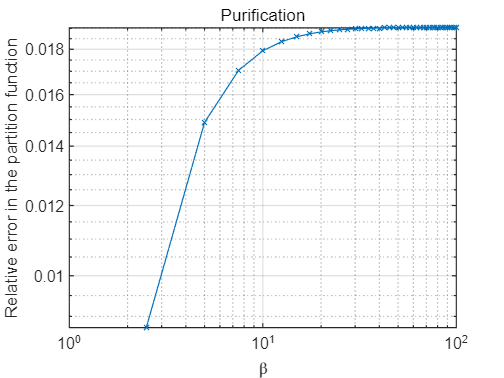

betas = taus*2;

% exact values
epsk = J*cos((1:L).'*(pi/(L+1)));
lnZexact = sum(log(1+exp(epsk.*(-betas))),1);

figure;
plot(betas,lnZs./lnZexact-1,'-x','LineWidth',1);
set(gca,'XScale','log','YScale','log','FontSize',13,'LineWidth',1)
grid on;
title('Purification');
xlabel('\beta')
ylabel('Relative error in the partition function');

## Exercise (c): Complete the function for the XTRG

Now let's complete `XTRG_Ex.m`, which is in the same sub-directory, for the XTRG. Fill out the parts of `XTRG_Ex.m` enclosed by the comments `TODO (start)` and `TODO (end)`.

You can verify your work by running the following script. The `XTRG_Ex.m` takes the MPO Hamiltonian as the input.

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

And we determine the initial value of the inverse temperature $\tau_0$ so that one can reach $\tau_\max = 100$ in 40 steps.

tmax = beta;
dt = tmax/(2^Nstep);

[taus,lnZs2,rho] = XTRG_Ex (Hs,dt,tmax,Nkeep,Nsweep);

Finite T: XTRG
N = 20, Nkeep = 40, Nsweep = 4, dt = 9.095e-11, tmax = 100 (40 steps)
22-10-12 22:37:15 | #4/40 : t = 1.455e-09/100
22-10-12 22:37:16 | #8/40 : t = 2.328e-08/100
22-10-12 22:37:16 | #12/40 : t = 3.725e-07/100
22-10-12 22:37:16 | #16/40 : t = 5.96e-06/100
22-10-12 22:37:16 | #20/40 : t = 9.537e-05/100
22-10-12 22:37:17 | #24/40 : t = 0.001526/100
22-10-12 22:37:17 | #28/40 : t = 0.02441/100
22-10-12 22:37:30 | #32/40 : t = 0.3906/100
22-10-12 22:38:05 | #36/40 : t = 6.25/100
22-10-12 22:38:40 | #40/40 : t = 100/100
Elapsed time: 84.76s, CPU time: 2228s, Avg # of cores: 26.28
22-10-12 22:38:40 | Memory usage : 2.49GiB


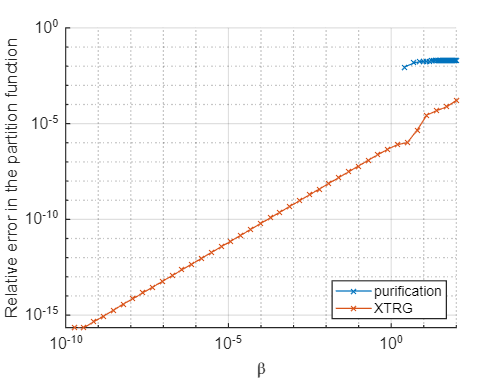


betas2 = taus;

% exact values
epsk = J*cos((1:L).'*(pi/(L+1)));
lnZexact2 = sum(log(1+exp(epsk.*(-betas2))),1);

figure;
hold on
plot(betas,abs(lnZs./lnZexact-1),'-x','LineWidth',1);
plot(betas2,abs(lnZs2./lnZexact2-1),'-x','LineWidth',1);
hold off
set(gca,'XScale','log','YScale','log','FontSize',13,'LineWidth',1)
grid on;
%title('XTRG');
xlabel('\beta')
ylabel('Relative error in the partition function');
legend({'purification', 'XTRG'},'Location','southeast');

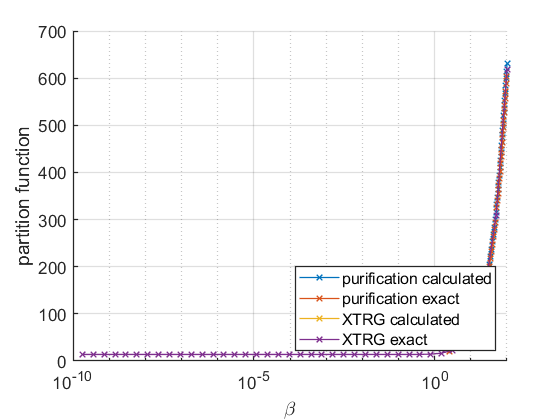

figure;
hold on
%plot(betas,lnZs,'-x','LineWidth',1);
%plot(betas,lnZexact,'-x','LineWidth',1);

plot(betas2,lnZs2,'-x','LineWidth',1);
plot(betas2,lnZexact2,'-x','LineWidth',1);

hold off
set(gca,'XScale','log','YScale','log','FontSize',13,'LineWidth',1)
grid on;
%title('XTRG');
xlabel('\beta')
ylabel('partition function');
legend({'purification calculated','purification exact', 'XTRG calculated', 'XTRG exact'},'Location','southeast');

We find that the XTRG is faster and more accurate. The latter advantage comes from the fact that it's free from the Trotter decomposition.